# Direct dynamics problem based on Newton-Euler Equations  using a Naive algorithm

## Related slides:

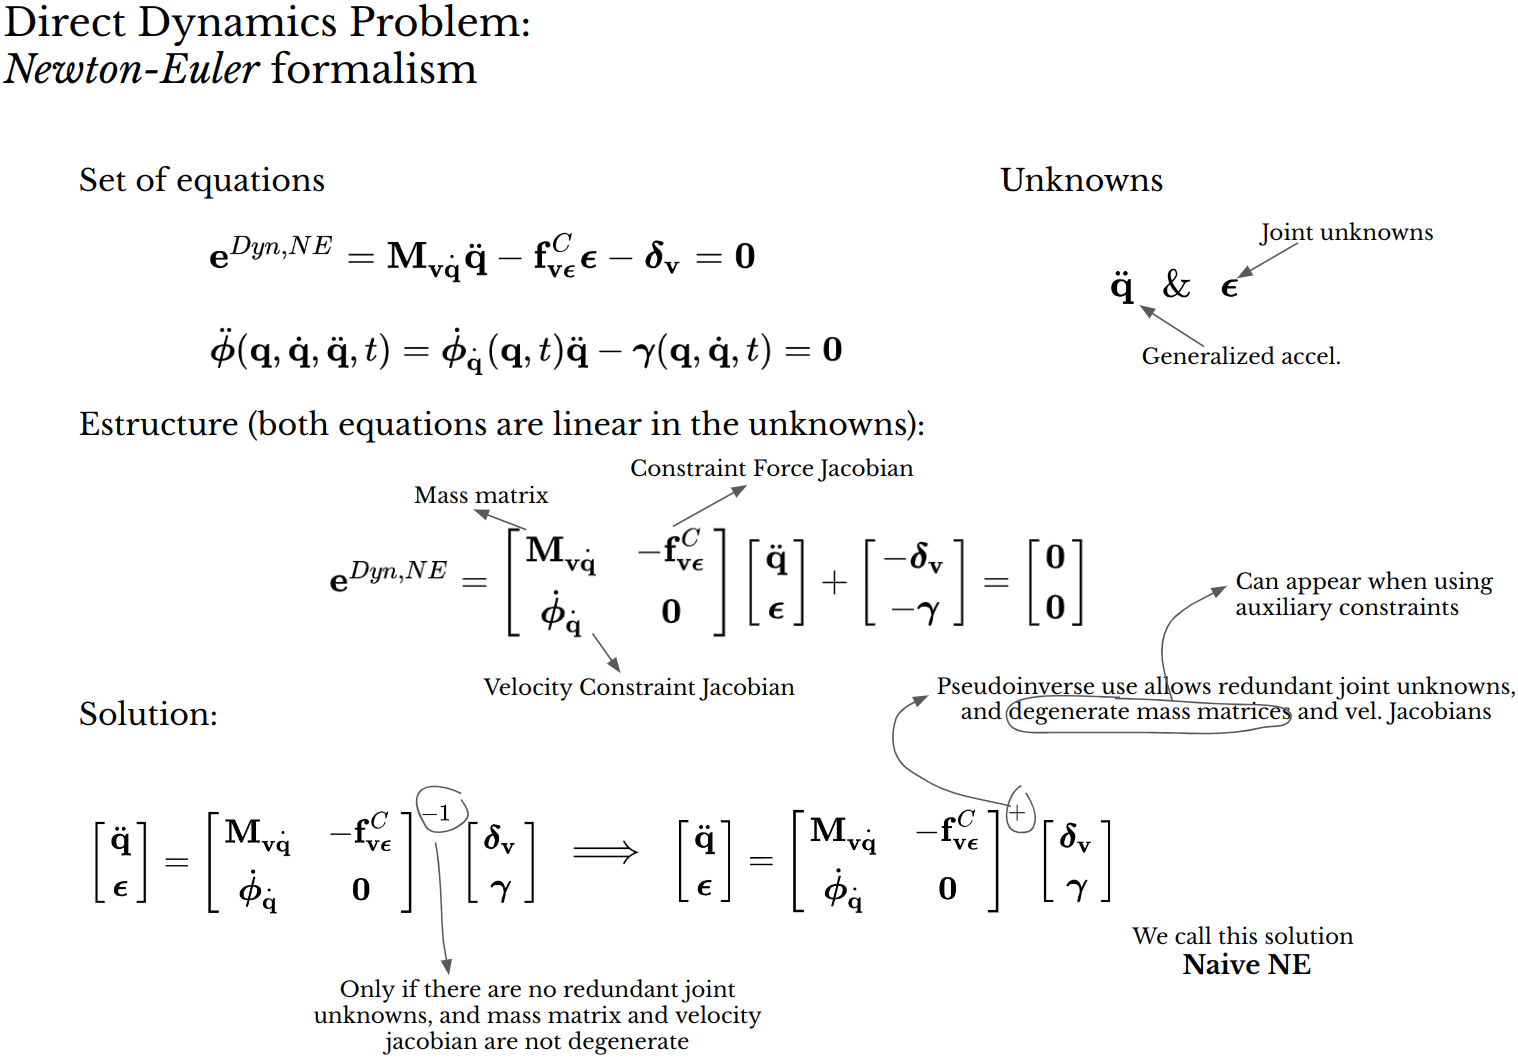

## Commented code:

Solve  $\mathbf{e}^{D y n, N E}=\mathbf{0}$ along with $\ddot{\mathbf{\phi}}=\mathbf{0}$ for $\ddot{\mathbf{q}}$ and $\mathbf{\epsilon}$using the a trivial (Naive) algorithm.  These equations are assembled in a full linear system of equations that is solved using the pseudoinverse. This avoids problems associated to dependent/zero constraint equations and redundant constraint forces. A minimum norm solution is given for the not fully determined subset of the constraint unknowns vector $\mathbf{\epsilon}$.

function [ddq_value,epsilon_value]=ddq_epsilon_from_Newton_Euler_Naive(q_value, dq_value, t_value, param_value)

global n_ddq n_epsilon
global n_ddPhi

Newton-Euler Dynamics equations along with constraint equations at the acceleration level:


$$$\mathbf{e}^{D y n, N E}=\mathbf{M}_{\mathbf{v} \dot{\mathbf{q}}} \ddot{\mathbf{q}}-\mathbf{f}_{\mathbf{v} \epsilon}^C \mathbf{\epsilon}-\mathbf{\delta}_{\mathbf{v}}=\mathbf{0}$$$



$$$\ddot{\phi}(\mathbf{q}, \dot{\mathbf{q}}, \ddot{\mathbf{q}}, t)=\dot{\phi}_{\dot{\mathbf{q}}}(\mathbf{q}, t) \ddot{\mathbf{q}}-\gamma(\mathbf{q}, \dot{\mathbf{q}}, t)=\mathbf{0}$$$


are solved for $\ddot{\mathbf{q}}$ and $\mathbf{\epsilon}$ 


$$$\mathbf{e}^{D y n, N E}=\left[\begin{array}{cc}\mathbf{M}_{\mathbf{v}} & -\mathbf{f}_{\mathrm{v} \epsilon}^C \\ \dot{\phi}_{\dot{\mathbf{q}}} & \mathbf{0}\end{array}\right]\left[\begin{array}{l}\ddot{\mathbf{q}} \\ \mathbf{\epsilon}\end{array}\right]+\left[\begin{array}{c}-\mathbf{\delta}_{\mathbf{v}} \\ -\mathbf{\gamma}\end{array}\right]=\left[\begin{array}{l}\mathbf{0} \\ \mathbf{0}\end{array}\right]$$$


by the most trivial algorithm:


$$$\left[\begin{array}{c}\ddot{\mathbf{q}} \\ \mathbf{\epsilon}\end{array}\right]=\left[\begin{array}{cc}\mathbf{M}_{\mathbf{v} \dot{\mathbf{q}}} & -\mathbf{f}_{\mathbf{v} \epsilon}^C \\ \dot{\phi}_{\dot{\mathbf{q}}} & \mathbf{0}\end{array}\right]^{+}\left[\begin{array}{c}\mathbf{\delta}_{\mathbf{v}} \\ \mathbf{\gamma}\end{array}\right]$$$


FC_vepsilon_value=FC_vepsilon_(q_value,t_value,param_value);
coeff_matrix_A=[M_vq_(q_value,t_value,param_value),-FC_vepsilon_value;
    dPhi_dq_(q_value,t_value,param_value),zeros(n_ddPhi,n_epsilon)];

indep_term_vector_b=[delta_v_(q_value,dq_value,t_value,param_value);
    gamma_(q_value,dq_value,t_value,param_value)];

unknown_vector_x=pinv(coeff_matrix_A)*indep_term_vector_b;

ddq_value=unknown_vector_x(1:n_ddq,1);
epsilon_value=unknown_vector_x(n_ddq+1:n_ddq+n_epsilon,1);

end